Network analysis for the iron interaction network

## Figure 3a

clear
clc

color_3classes=[0,153,62;
    242,150,0;
    195,13,35]/255;

addpath('./Tools/')
datapath_mat='./data/outputrec.mat';
raw=load(datapath_mat);
outputrec=raw.outputrec;
clear raw;

colorpath='./data/colorcode_new.csv';


Input the habitant information

habitantinfor='./data/1928strain_country_infor_1.xlsx';
hab_raw=importdata(habitantinfor);

outputrec.unistrains.unihabitants={'human','plant','soil','water','unknown','others'};
for i=1:length(outputrec.unistrains.name)
    strtemp=outputrec.unistrains.name{i};
    uniname=strtemp;
    loc_inhab=find(strcmp(hab_raw(:,1),uniname));
    if ~isempty(loc_inhab)
        outputrec.unistrains.habitant{i,1}=hab_raw{loc_inhab,2};
        outputrec.unistrains.habitant_id(i,1)=find(strcmp(outputrec.unistrains.unihabitants,outputrec.unistrains.habitant{i,1}));
    else
        error('err')
    end
end
%%%%% analyze each behavior's habitant
tabulate(outputrec.unistrains.habitant)

    Value    Count   Percent
    water      124      6.43%
    human      409     21.21%
   others      137      7.11%
  unknown      762     39.52%
     soil      262     13.59%
    plant      234     12.14%



for b=1:size(outputrec.unibehaviors,1)
    strainlist_thisbehave=find(outputrec.unistrains.behav_id==b);

    hablist=outputrec.unistrains.habitant_id(strainlist_thisbehave);
    for j=1:length(outputrec.unistrains.unihabitants)
        outputrec.unibehavior_habitantcomp(b,j)=sum(hablist==j);
    end
end
%%% how many rec groups are there, how many has colors, and how many has selfreceptors
maxrecgroup=max(outputrec.rec_groupid);
normbehav_habitantcomp=outputrec.unibehavior_habitantcomp./repmat(sum(outputrec.unibehavior_habitantcomp,2),1,size(outputrec.unibehavior_habitantcomp,2));
D = pdist(normbehav_habitantcomp);
% hab diffrence
hab_diff=squareform(D);
tree = linkage(D,'average');
leafOrder = optimalleaforder(tree,D);

output to cytoscape

toremoverecgroup=find(outputrec.group_recnum_selfnum_purenum(:,2)==0);
outputcyto=0;
if outputcyto
    outputpath='./output/cytoscope_ironnetwork_1013/cytoscape_ironnet_20240407_';

  
    sid_touse_list=setdiff(1:maxrecgroup,toremoverecgroup);
    % a strain is named by: Pure-s/Partial-s-rn/Cheater-rn;
    % a siderophore is named by :sid-n
    outputrec.unibehav_name=[];
    outputrec.unibehav_size=[];
    outputrec.unibehav_type=[];% 1: pure; 2:partial;3: cheater
    for b=1:size(outputrec.unibehaviors,1)
        strainlist_thisbehave=find(outputrec.unistrains.behav_id==b);
        outputrec.unibehav_size(b,1)=length(strainlist_thisbehave);

        % whether pure, partial, or cheater
        sidgroup=outputrec.unibehaviors(b,1);
        recgroups=outputrec.unibehaviors(b,2:end);
        recgroups=recgroups(recgroups>0);

        recnum=length(recgroups);
        behavname='';
        if sidgroup==0% cheater
            outputrec.unibehav_type(b,1)=3;
            behavname=['Cheater-r(',num2str(recnum),'):b',num2str(b)];
        elseif recnum==1 % pure producer
            outputrec.unibehav_type(b,1)=1;
            behavname=['Pure-s',num2str(sidgroup),':b',num2str(b)];
        else% partial producer
            outputrec.unibehav_type(b,1)=2;
            behavname=['Partial-s',num2str(sidgroup),'-r(',num2str(recnum),')',':b',num2str(b)];
        end
        outputrec.unibehav_name{b,1}=behavname;

    end
    outputrec.groupname=[];
    for i=1:maxrecgroup
        outputrec.groupname{i,1}=['sid-',num2str(i)];
    end



    % output the network by behaviors
    netfid=fopen([outputpath,'network.csv'],'w+')
    fprintf(netfid,'source,target,isproduce,edgesize,edgecolor\n');
    for b=1:size(outputrec.unibehaviors,1)
        sidgroup=outputrec.unibehaviors(b,1);
        recgroups=outputrec.unibehaviors(b,2:end);
        recgroups=recgroups(recgroups>0);

        recgroups=setdiff(recgroups,toremoverecgroup);
        if length(recgroups)>0
            behav_size=outputrec.unibehav_size(b);

            % strains produce siderophore
            if sidgroup>0
                edgecolorstr= rgb2hex([0,0,0]);%outputrec.hexcolor{sidgroup};% defined the siderophore related
                fprintf(netfid,'%s,%s,1,%d,%s\n',outputrec.unibehav_name{b},outputrec.groupname{sidgroup},behav_size,edgecolorstr);
            end
            for r=1:length(recgroups) % siderophore being utilized by...
                rid=recgroups(r);
                edgecolorstr= outputrec.hexcolor{rid};% defined the siderophore related
                fprintf(netfid,'%s,%s,0,%d,%s\n',outputrec.groupname{rid},outputrec.unibehav_name{b},1,edgecolorstr);
            end

            % distance with another behavior
            behavdistthresh=-1;
            for b2=(b+1):size(outputrec.unibehaviors,1)
                sidgroup=outputrec.unibehaviors(b2,1);
                recgroups=outputrec.unibehaviors(b2,2:end);
                recgroups=recgroups(recgroups>0);

                recgroups=setdiff(recgroups,toremoverecgroup);
                if length(recgroups)>0
                    if hab_diff(b,b2)<behavdistthresh
                        edgecolorstr= rgb2hex(0.9*[1,1,1]);
                        fprintf(netfid,'%s,%s,-1,%f,%s\n',outputrec.unibehav_name{b},outputrec.unibehav_name{b2},max(hab_diff(:))-hab_diff(b,b2),edgecolorstr);
                    end
                end
            end

        end




    end
    fclose(netfid);

    % output the node properties
    nodefid=fopen([outputpath,'nodespro.csv'],'w+');
    fprintf(nodefid,['nodename,issid,nodesize,straintype,color,',strjoin(outputrec.unistrains.unihabitants,','),'\n']);
    % siderophore groups
    for r=1:maxrecgroup
        if ~ismember(r,toremoverecgroup)
            % size: how many strains producing this one
            colorstr=outputrec.hexcolor{r};
            producernum=outputrec.group_recnum_selfnum_purenum(r,2);
            fprintf(nodefid,'%s,1,%d,nan,%s\n',outputrec.groupname{r},producernum+50,colorstr);
        end
    end
    % strain groups
    for b=1:size(outputrec.unibehaviors,1)
        sidgroup=outputrec.unibehaviors(b,1);
        recgroups=outputrec.unibehaviors(b,2:end);
        recgroups=recgroups(recgroups>0);
        recgroups=setdiff(recgroups,toremoverecgroup);

        if length(recgroups)>0
            % color by habitants
            hablist=outputrec.unibehavior_habitantcomp(b,:);
            hablist=hablist/sum(hablist);

            %{'human','plant','soil','water','unknown','others'};
            habcolor=[1,0,0;
                0,1,0;
                1,0.75,0; % socil
                0,0,1;
                0,0,0;
                1,1,1];
            colorstr=rgb2hex(hablist*habcolor);

            straintype=outputrec.unibehav_type(b);
            
            % not color by habitant
            colorstr='nan';%rgb2hex(color_3classes(straintype,:));

            fprintf(nodefid,'%s,0,%d,%d,%s',outputrec.unibehav_name{b},outputrec.unibehav_size(b),straintype,colorstr);
            fprintf(nodefid,',%d',outputrec.unibehavior_habitantcomp(b,:));
            fprintf(nodefid,'\n');
        end
    end

    fclose(nodefid);
end



## Figure3b

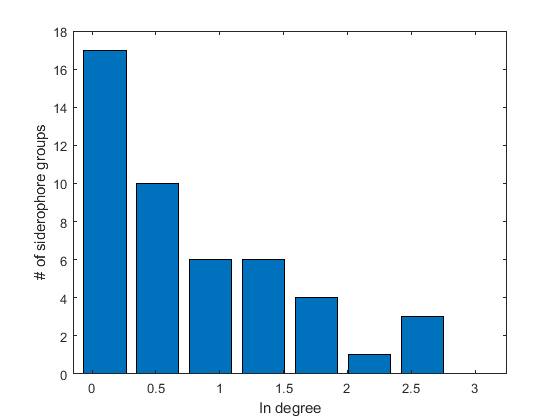

goodrecs=find(outputrec.group_recnum_selfnum_purenum(:,2)>0); % the group should be produced

figure;

data=outputrec.group_recnum_selfnum_purenum(goodrecs,2);

toshowdata=log10(data);
toshowdata(isinf(toshowdata))=[];

barcenters=linspace(0.1,3,8);
[histb,~]=hist(toshowdata,barcenters);
bar(barcenters,histb)
xlim([min(barcenters)-0.25,max(barcenters)+0.25])
xlabel('In degree')
ylabel('# of siderophore groups')

## Figure3c

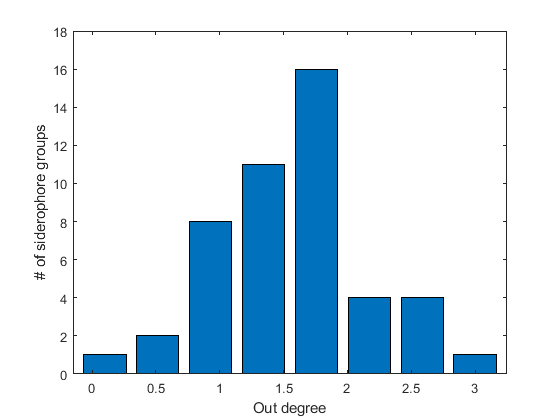

figure;

data=outputrec.group_recnum_selfnum_purenum(goodrecs,1);

toshowdata=log10(data);
toshowdata(isinf(toshowdata))=[];

barcenters=linspace(0.1,3,8);
[histb,~]=hist(toshowdata,barcenters);
bar(barcenters,histb)

xlim([min(barcenters)-0.25,max(barcenters)+0.25])
ylim([0,18])
xlabel('Out degree')
ylabel('# of siderophore groups')

## Figure 3defg

clear
clc
if ~exist('./output/cytoscope_ironnetwork_1013/cytoscape_ironnet_humannetwork.csv','file')
    if ~exist('./output/recgroup_new.mat','file')
            
        infor=importdata('./data/1928strain_country_infor_1.xlsx');
        infor=infor.textdata(2:end,:);
        recgroup=readtable('./data/recgroup_new.csv');
        
        %Add the strain's habitat and isolation to the recgroup
        for i=1:size(recgroup,1)
            name1=recgroup.strainnemes{i};
            for j=1:length(infor)
                name2=infor{j,1};
                if strcmp(name1,name2)
                    recgroup.country{i}=infor{j,2};
                    recgroup.isolation{i}=infor{j,3};
                end
            end
        end
        save('./output/recgroup_new.mat',"recgroup");
    else
        load('./output/recgroup_new.mat');
    end
        
    colorpath='./data/colorcode_new.csv';
    addpath('./Tools/')       
    
    color_3classes=[0,153,62;
        242,150,0;
        195,13,35]/255;
    outputrec=[];
    
    %Add habitats and countries
    outputrec.country=recgroup.country;
    outputrec.isolation=recgroup.isolation;
    isolation_1=tabulate(outputrec.isolation);
    isolation=isolation_1([1,4,5,6],:);
    
    for gsh=1:length(isolation)
        if gsh==5
            a=1:length(outputrec.isolation);
        else
            a=ismember(outputrec.isolation,isolation(gsh,1));
        end
    
        outputrec.rectype=recgroup.sptypeid(a);% is self
        outputrec.rec_groupid=recgroup.Rec_groupid(a);
        outputrec.strainname=recgroup.strainnemes(a);
    
        [outputrec.unistrains.name,~,outputrec.strainid]=unique(outputrec.strainname);
        
        outputrec.recnum=length(outputrec.strainid);
        
        % import color assignment
        T=readtable(colorpath);
        outputrec.hexcolor=T.Hex;
        
        %statistics 
        
        % each strain: how many syn, rec
        % Aalso construct the "behavior" list for each strain: the self-rec group; allgroup type
        outputrec.unistrains.behavior=[];
        for i=1:length(outputrec.unistrains.name)
            reclist=find(outputrec.strainid==i);
            selfrec=reclist(outputrec.rectype(reclist)<3);
            if isempty(selfrec)
                syngroup=0;
            else
                syngroup=outputrec.rec_groupid(selfrec);
            end
            outputrec.unistrains.synnum(i,1)=length(selfrec);% 1 or 2
            outputrec.unistrains.recnum(i,1)=length(reclist);
            
            behave_list=[syngroup,sort(outputrec.rec_groupid(reclist)')];
            outputrec.unistrains.behavior(i,1:length(behave_list))=behave_list;
        end
        
        purelist=find(outputrec.unistrains.synnum==1 & outputrec.unistrains.recnum==1);
        partiallist=setdiff(find(outputrec.unistrains.synnum==1),purelist);
        cheaterlist=find(outputrec.unistrains.synnum==0);
        
        
        
        %%% output distribution figures;
        tbl=tabulate(outputrec.unistrains.recnum);
        recperstrain=tbl(:,1);
        straincount=tbl(:,2);
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%% how many rec groups are there, how many has colors, and how many has selfreceptors
        maxrecgroup=max(outputrec.rec_groupid);
        outputrec.group_recnum_selfnum_purenum=zeros(maxrecgroup,3);
        outputrec.edgecolor=ones(maxrecgroup,3);
        
        for g=1:maxrecgroup
            thisglist=find(outputrec.rec_groupid==g);
            
            thisg_recnum=length(thisglist);
            thisg_selfnum=sum(outputrec.rectype(thisglist)<3);
            thisg_purenum=sum(outputrec.rectype(thisglist)<2);
            outputrec.group_recnum_selfnum_purenum(g,:)=[thisg_recnum,thisg_selfnum,thisg_purenum];
        
            if thisg_purenum==0 
                if  thisg_selfnum>0
                    % a gray one: not in pure but self in partial
                    outputrec.hexcolor{g}=rgb2hex([1,1,1]*0.75);
                    outputrec.edgecolor(g,:)=[1,1,1]*0;
                else
                    % black: dispensable group
                    outputrec.hexcolor{g}=rgb2hex([1,1,1]*0);
                    outputrec.edgecolor(g,:)=[1,1,1]*0;
                end 
            end
        end
        
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        [outputrec.unibehaviors,~,outputrec.unistrains.behav_id]=unique(outputrec.unistrains.behavior,'rows');
        
        
        fprintf('In total, there are %d strains, %d receptors\n',length(outputrec.unistrains.name),outputrec.recnum);
        fprintf('Among them, %d pure, %d partial, %d cheaters\n',length(purelist),length(partiallist),length(cheaterlist));
        fprintf('on average, partial has %0.2f receptors, cheater has %0.2f recetpors',sum(outputrec.unistrains.recnum(partiallist))/length(partiallist),sum(outputrec.unistrains.recnum(cheaterlist))/length(cheaterlist));
        
        fprintf('In total, %d rec groups,\n\tout of which %d groups appeared in pure, taking %0.2f of all receptors;\n\t%d groups appeared with at least one self, taking %0.2f of receptors',maxrecgroup, sum(outputrec.group_recnum_selfnum_purenum(:,3)>0),sum(outputrec.group_recnum_selfnum_purenum(outputrec.group_recnum_selfnum_purenum(:,3)>0,1))/sum(outputrec.group_recnum_selfnum_purenum(:,1)), sum(outputrec.group_recnum_selfnum_purenum(:,2)>0), sum(outputrec.group_recnum_selfnum_purenum(outputrec.group_recnum_selfnum_purenum(:,2)>0,1))/sum(outputrec.group_recnum_selfnum_purenum(:,1)))
        
        fprintf('there are %d unique behaviors for strains\n', size(outputrec.unibehaviors,1));
        
        
        %output to cytoscape 
        outputpath='./output/cytoscope_ironnetwork_1013/cytoscape_ironnet_';
        
        toremoverecgroup=find(outputrec.group_recnum_selfnum_purenum(:,2)==0);
        
        % a strain is named by: Pure-s/Partial-s-rn/Cheater-rn; 
        % a siderophore is named by :sid-n
        outputrec.unibehav_name=[];
        outputrec.unibehav_size=[];
        outputrec.unibehav_type=[];% 1: pure; 2:partial;3: cheater
        for b=1:size(outputrec.unibehaviors,1)
            strainlist_thisbehave=find(outputrec.unistrains.behav_id==b);
            outputrec.unibehav_size(b,1)=length(strainlist_thisbehave);
            
            % whether pure, partial, or cheater
            sidgroup=outputrec.unibehaviors(b,1);
            recgroups=outputrec.unibehaviors(b,2:end);
            recgroups=recgroups(recgroups>0);
            
            recnum=length(recgroups);
            behavname='';
            if sidgroup==0% cheater
                outputrec.unibehav_type(b,1)=3;
                behavname=['Cheater-r(',num2str(recnum),'):b',num2str(b)];
            elseif recnum==1 % pure producer
                outputrec.unibehav_type(b,1)=1;
                behavname=['Pure-s',num2str(sidgroup),':b',num2str(b)];
            else% partial producer
                outputrec.unibehav_type(b,1)=2;
                behavname=['Partial-s',num2str(sidgroup),'-r(',num2str(recnum),')',':b',num2str(b)];
            end
            outputrec.unibehav_name{b,1}=behavname;
            
        end
        outputrec.groupname=[];
        for i=1:maxrecgroup
            outputrec.groupname{i,1}=['sid-',num2str(i)];
        end
         
        
        
        % output the network by behaviors
       
       %netfid=fopen([outputpath,'whole','network.csv'],'w+');%all
       
       netfid=fopen([outputpath,isolation{gsh,1},'network.csv'],'w+');%isolation
         
        fprintf(netfid,'source,target,isproduce,edgesize,edgecolor\n');
        for b=1:size(outputrec.unibehaviors,1)
            sidgroup=outputrec.unibehaviors(b,1);
            recgroups=outputrec.unibehaviors(b,2:end);
            recgroups=recgroups(recgroups>0);
            
            recgroups=setdiff(recgroups,toremoverecgroup);
            if length(recgroups)>0
                behav_size=outputrec.unibehav_size(b);
                
                % strains produce siderophore
                if sidgroup>0
                    edgecolorstr= rgb2hex([0,0,0]);%outputrec.hexcolor{sidgroup};% defined the siderophore related
                    fprintf(netfid,'%s,%s,1,%d,%s\n',outputrec.unibehav_name{b},outputrec.groupname{sidgroup},behav_size,edgecolorstr);
                end
                for r=1:length(recgroups) % siderophore being utilized by...
                    rid=recgroups(r);
                    edgecolorstr= outputrec.hexcolor{rid};% defined the siderophore related
                    fprintf(netfid,'%s,%s,0,%d,%s\n',outputrec.groupname{rid},outputrec.unibehav_name{b},1,edgecolorstr);
                end
            end
        end
        fclose(netfid);
        
        % output the node properties
        %nodefid=fopen([outputpath,'whole','nodespro.csv'],'w+');%all
       nodefid=fopen([outputpath,isolation{gsh,1},'nodespro.csv'],'w+');%isolation
      
        fprintf(nodefid,'nodename,issid,nodesize,straintype,color\n');
        % siderophore groups
        for r=1:maxrecgroup
            if ~ismember(r,toremoverecgroup)
                % size: how many strains producing this one
                colorstr=outputrec.hexcolor{r};
                producernum=outputrec.group_recnum_selfnum_purenum(r,2);
                fprintf(nodefid,'%s,1,%d,nan,%s\n',outputrec.groupname{r},producernum+50,colorstr);
            end
        end
        % strain groups
        for b=1:size(outputrec.unibehaviors,1)
            sidgroup=outputrec.unibehaviors(b,1);
            recgroups=outputrec.unibehaviors(b,2:end);
            recgroups=recgroups(recgroups>0);
            recgroups=setdiff(recgroups,toremoverecgroup);
            
            if length(recgroups)>0
                straintype=outputrec.unibehav_type(b);
                colorstr='nan';%rgb2hex(color_3classes(straintype,:));
                fprintf(nodefid,'%s,0,%d,%d,%s\n',outputrec.unibehav_name{b},outputrec.unibehav_size(b),straintype,colorstr);
            end
        end
        fclose(nodefid);
    end
end